# Create 3D Disc and Warp to Curvature Radius

This script is a pilot using some basic MATLAB features and those of the GIBBON toolbox to create an ellipse disc in 3D and then warp it so that it has a certain curvature radius. This process should theoretically be useful for creating the outer layer of cartilage that we want to fix to the glenoid surface.

First test out the basic 3D region meshing feature of GIBBON using their help example.

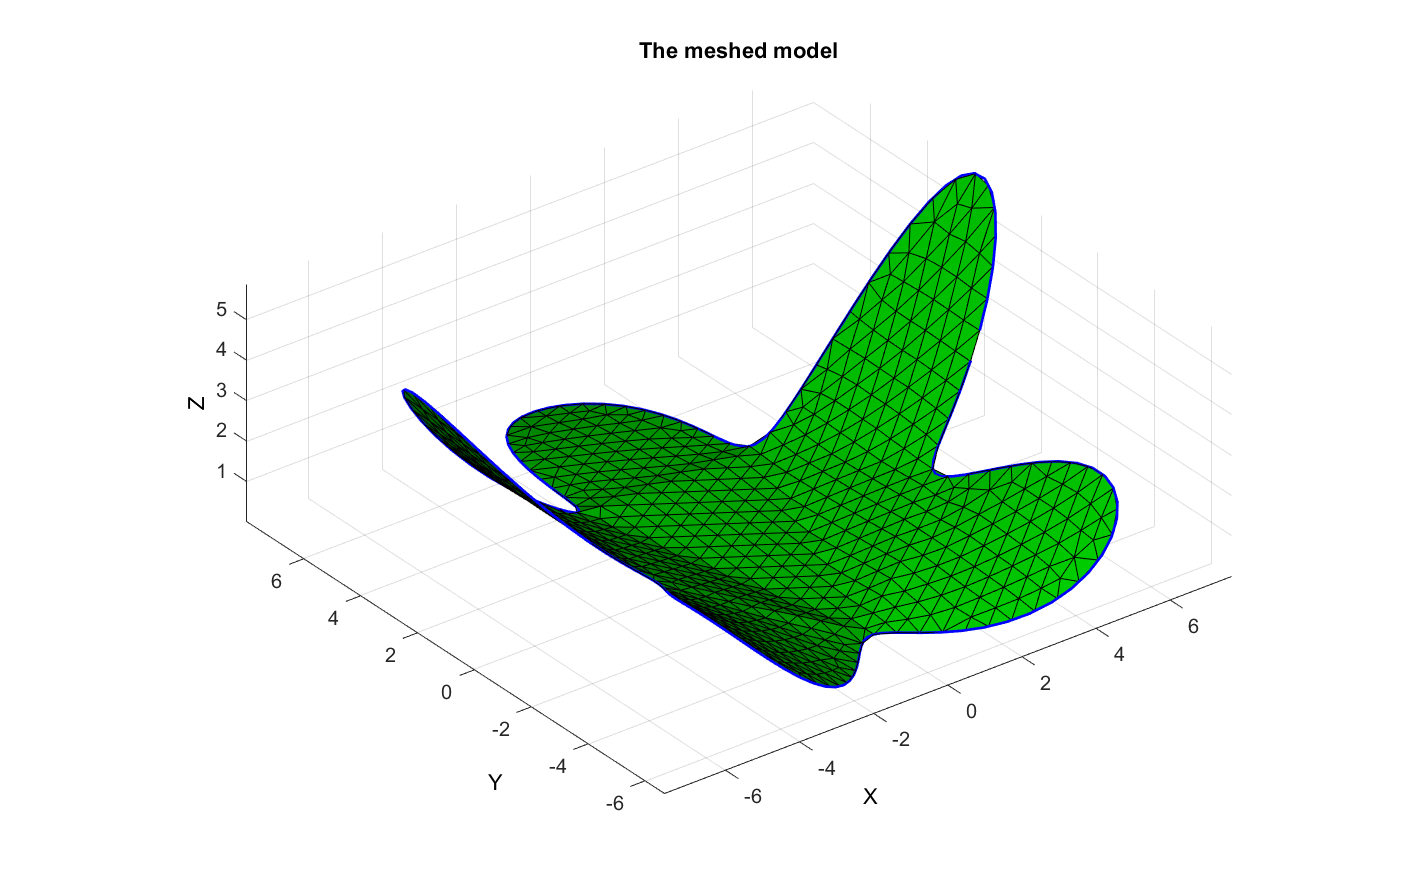

%Create a boundary to fill
%Note that tis boundary is discontinuous
ns = 150;
t = linspace(0,2*pi,ns);
t = t(1:end-1);
r = 6+2.*sin(5*t);
[x,y] = pol2cart(t,r);
z = 1/10*x.^2;
V1 = [x(:) y(:) z(:)];

%Place in the region cell for the meshing procedure
regionCell = {V1};

%Defining a region and control parameters (See also |regionTriMesh2D|)
pointSpacing = 0.5; %Desired point spacing
resampleCurveOpt = 1; %option for resampling the curve
interpMethod = 'linear'; %or 'natural'
[F,V] = regionTriMesh3D(regionCell,pointSpacing,resampleCurveOpt,interpMethod);

%Plot meshed model
hf1 = cFigure;
title('The meshed model','FontSize',15);
xlabel('X','FontSize',15);ylabel('Y','FontSize',15); zlabel('Z','FontSize',15);
hold on;
gpatch(F,V,'g');
plotV(V1,'b-','LineWidth',2);
axis equal; view(3); axis tight;  grid on;  set(gca,'FontSize',15);
camlight headlight;

Now run the above example on a flat ellipse shape (i.e. same Z-coordinates).

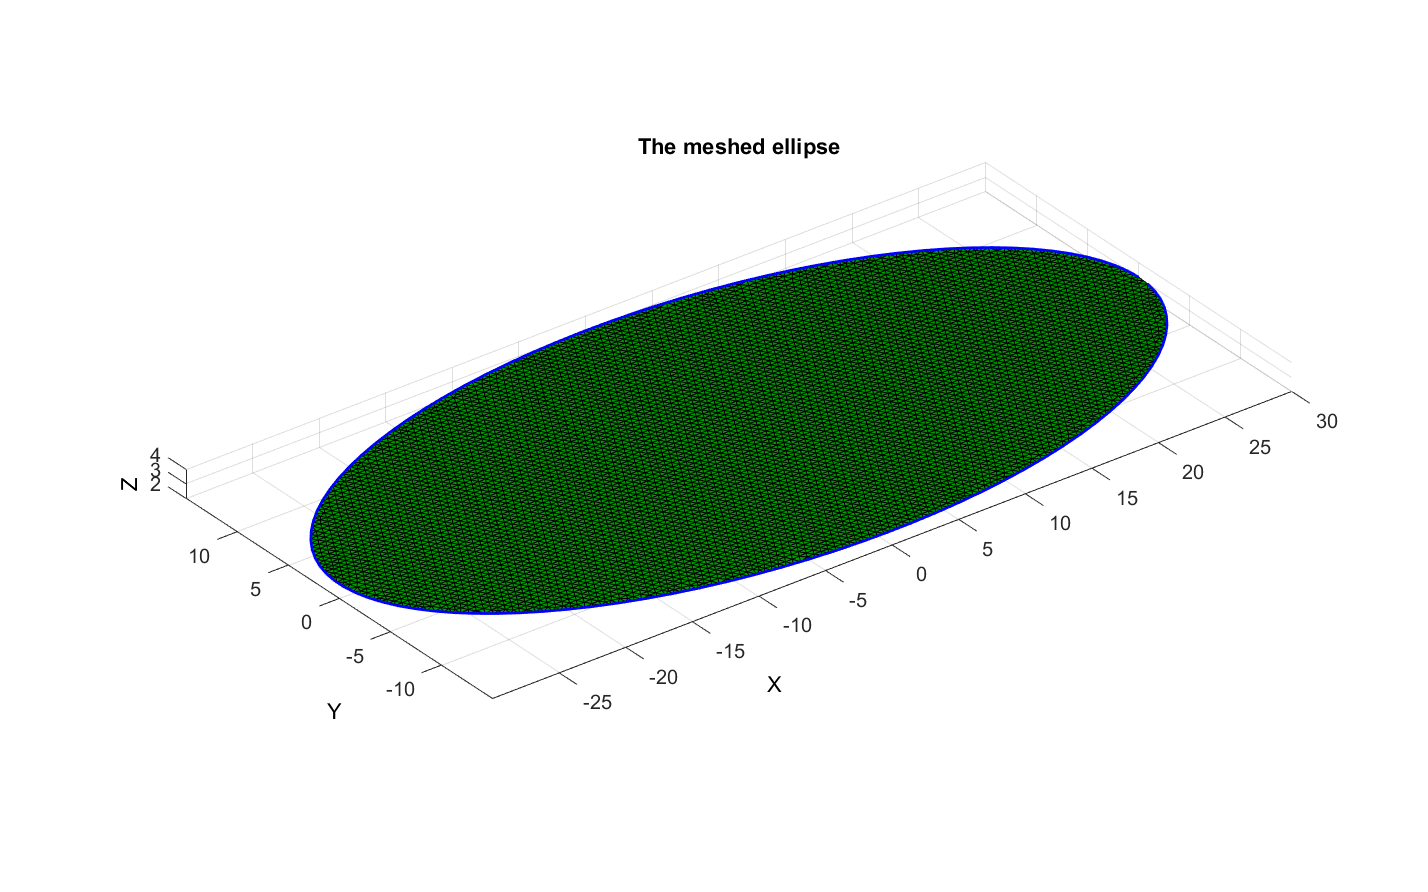

%Create the ellipse
t = linspace(0,2*pi) ;
a = 30 ; b = 15 ;
x = a*cos(t) ;
y = b*sin(t) ;

%Delete the last point to make discontinuous
x = x(1:end-1); y = y(1:end-1);

%Set 3D shape
V2 = [x(:) y(:) ones(length(x),1)*3];

%Place in the region cell for the meshing procedure
regionCellEllipse = {V2};

%Defining a region and control parameters (See also |regionTriMesh2D|)
[ellipseF,ellipseV] = regionTriMesh3D(regionCellEllipse,pointSpacing,resampleCurveOpt,interpMethod);

%Plot meshed model
hf1 = cFigure;
title('The meshed ellipse','FontSize',15);
xlabel('X','FontSize',15);ylabel('Y','FontSize',15); zlabel('Z','FontSize',15);
hold on;
gpatch(ellipseF,ellipseV,'g');
plotV(V2,'b-','LineWidth',2);
axis equal; view(3); axis tight;  grid on;  set(gca,'FontSize',15);
camlight headlight;

Next step is to try and warp this disc and give it a specific curvature radius. We'll try and set this to the curvature specified in the Walia et al. studies, that being a mean radius of curvature of 26.37.

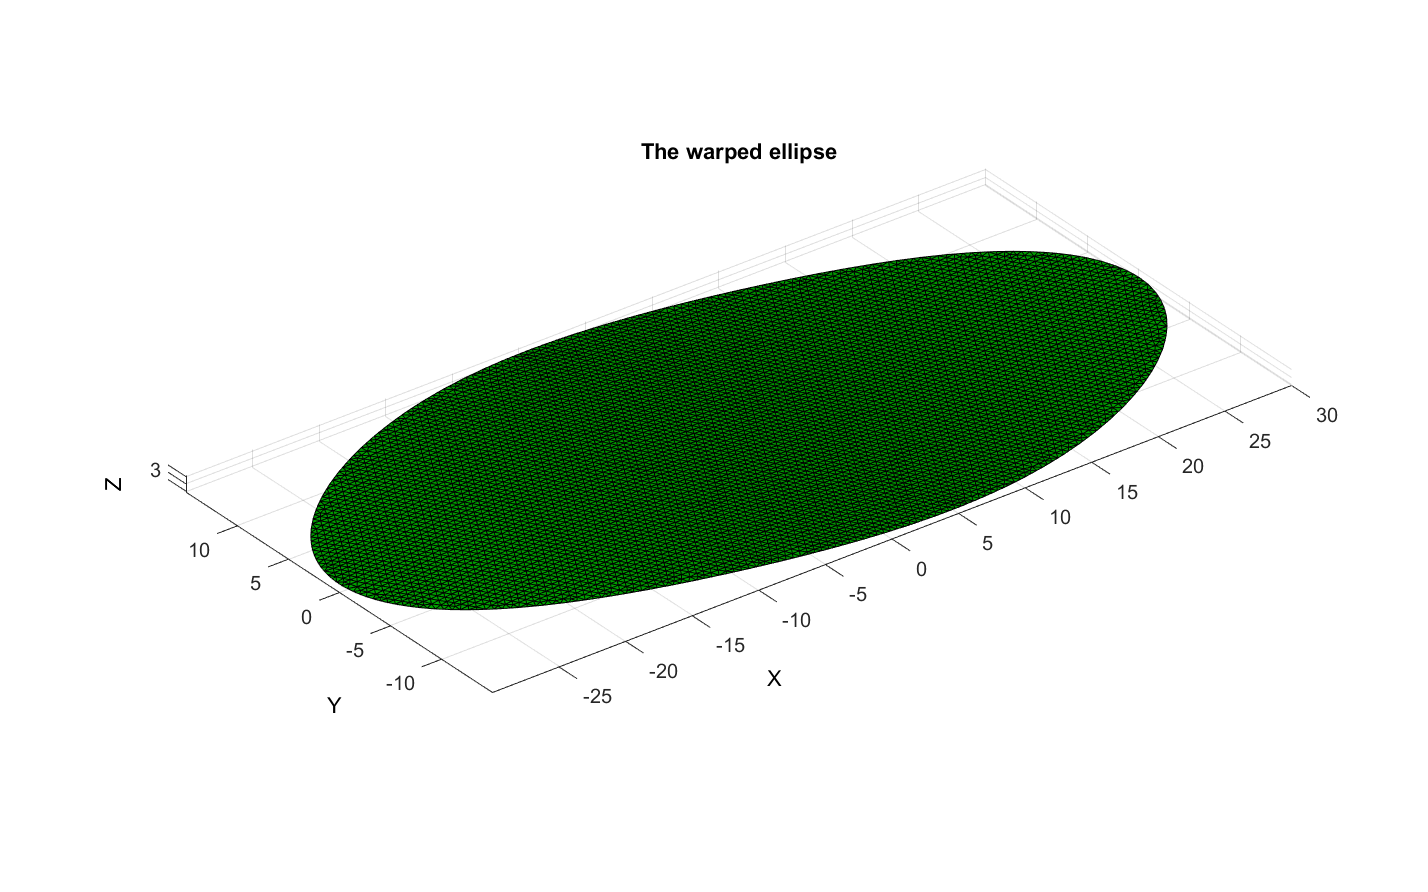

%Do a basic test of warping in the z-direction to see what happens
w = ellipseV(:,1); w = w-min(w(:)); w = w./max(w(:)); %Weight to use for warping
w = w*2*pi; %Metric to use in warping
ellipseV(:,3) = ellipseV(:,3) + 0.6 * sin(w); %Warp in Z-direction

hf1 = cFigure;
title('The warped ellipse','FontSize',15);
xlabel('X','FontSize',15);ylabel('Y','FontSize',15); zlabel('Z','FontSize',15);
hold on;
gpatch(ellipseF,ellipseV,'g');
axis equal; view(3); axis tight;  grid on;  set(gca,'FontSize',15);
camlight headlight;

The above basically warps it into the sine wave specification that is provided, so we need more of a quadratic curve that has the desired radius curvature that we're after.

%Reset the ellipse back to normal
[ellipseF,ellipseV] = regionTriMesh3D(regionCellEllipse,pointSpacing,resampleCurveOpt,interpMethod);

We want the disc to be perturbed relative to its max/min X and Y points relative to the centre, based on a quadratic polynomial. We know that at the mid point of the ellipse (i.e. mean of X and Y) that the perturbation to the disc should be zero, so that gives us one coordinate (i.e. [mean(X), 0]). At the max and min of the coordinates we want the disc to be perturbed upwards by the curvature radius maximum (i.e. 26.37), so that gives us the remaining two points (i.e. [min(X),26.37] & [max(X),26.37]). With these three coordinates we can fit a quadratic polynomial that will add to the Z value based on the curve fit to it.

%Create the 3 coordinate points for the X polynomial
x_Xpts = [min(ellipseV(:,1)), mean(ellipseV(:,1)), max(ellipseV(:,1))];
y_Xpts = [26.37, 0, 26.37]; %set to curvature radius

%Fit the x-polynomial and get the equation
x_P = polyfit(x_Xpts,y_Xpts,2);

%Create the 3 coordinate points for the Y polynomial
x_Ypts = [min(ellipseV(:,2)), mean(ellipseV(:,2)), max(ellipseV(:,2))];
y_Ypts = [26.37, 0, 26.37]; %set to curvature radius

%Fit the x-polynomial and get the equation
y_P = polyfit(x_Ypts,y_Ypts,2);

%Warp the disc Z-axis based on the two quadratic functions
ellipseV(:,3) = (polyval(x_P,ellipseV(:,1))) + (polyval(y_P,ellipseV(:,2)));

ellipseV =    30.0000         0   26.3700
   29.9684    0.4983   26.3435
   29.9311    0.9959   26.3653
   29.8374    1.4864   26.3440
   29.7345    1.9745   26.3623
   29.5823    2.4500   26.3445
   29.4203    2.9218   26.3617
   29.2148    3.3769   26.3446
   29.0025    3.8285   26.3640
   28.7496    4.2590   26.3444


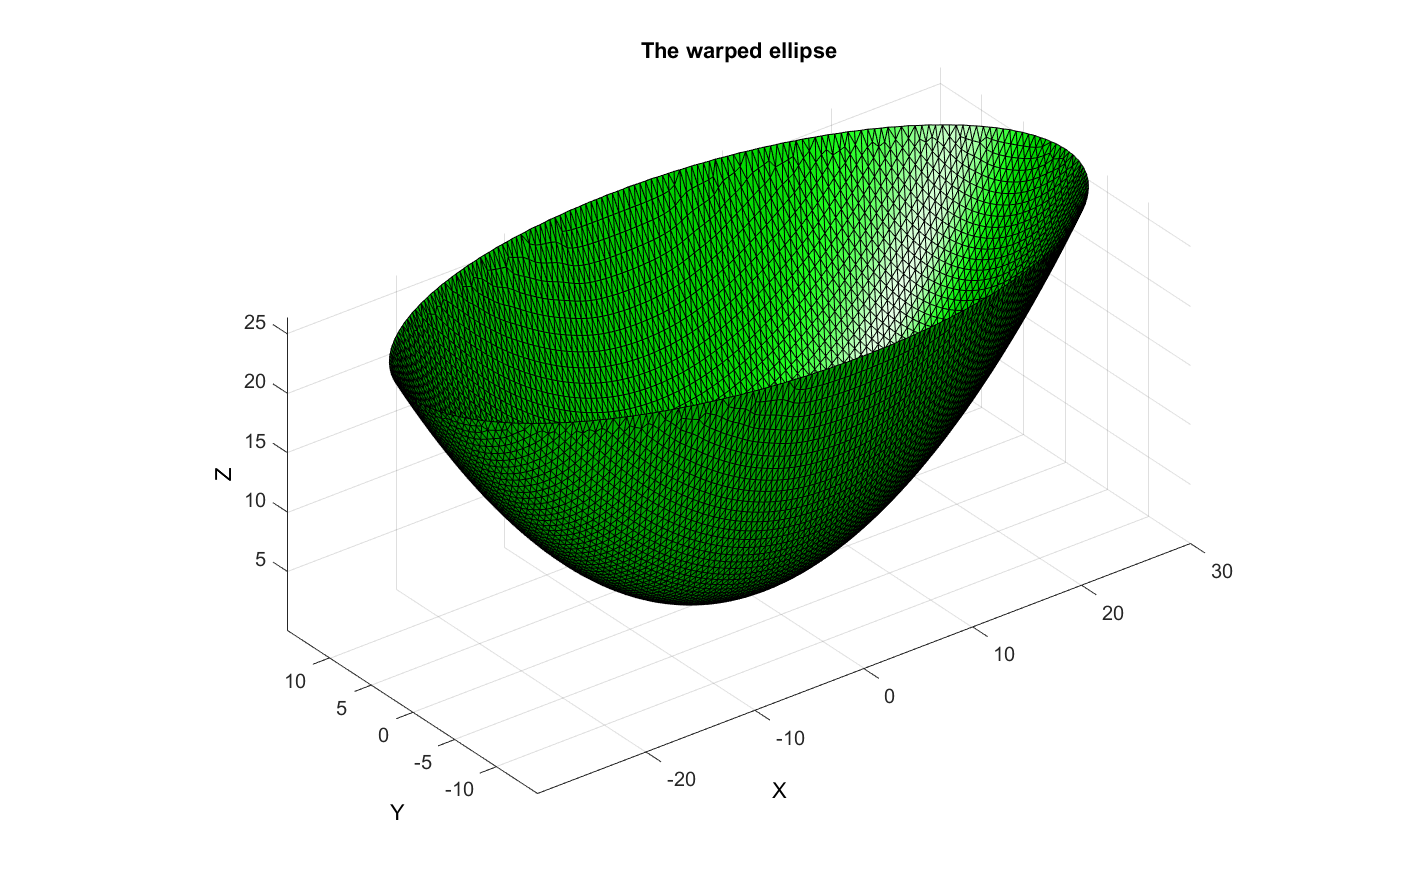


%Plot
hf1 = cFigure;
title('The warped ellipse','FontSize',15);
xlabel('X','FontSize',15);ylabel('Y','FontSize',15); zlabel('Z','FontSize',15);
hold on;
gpatch(ellipseF,ellipseV,'g');
axis equal; view(3); axis tight;  grid on;  set(gca,'FontSize',15);
camlight headlight;